# Task 2 - Semiconductor defect detection

## Read images

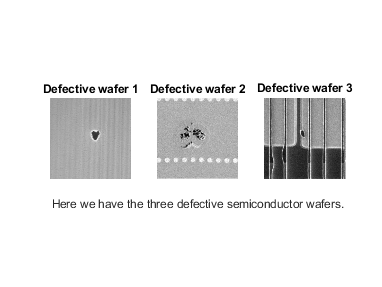

img_path = "images/final/task_2/";

image1 = imread(img_path + "defectivewafer1.jpg");
image2 = imread(img_path + "defectivewafer2.jpg");
image3 = imread(img_path + "defectivewafer3.jpg");

img1gray = rgb2gray(image1);
img2gray = rgb2gray(image2);
img3gray = rgb2gray(image3);

figure;
subplot(1, 3, 1); imshow(img1gray); title("Defective wafer 1");
subplot(1, 3, 2); imshow(img2gray); title("Defective wafer 2");
xlabel("Here we have the three defective semiconductor wafers.");
subplot(1, 3, 3); imshow(img3gray); title("Defective wafer 3");

## Isolate Defects

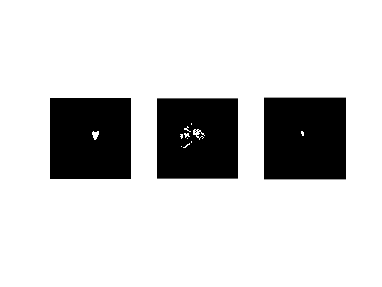

% First 2 images work with just default binarization
img1bw = imbinarize(img1gray);
img1bw_rev = imcomplement(img1bw);

img2bw = imbinarize(img2gray);
img2bw_rev = imcomplement(img2bw);

% Third image needs more filtering
img3bw = imbinarize(img3gray);
img3bw_rev = imcomplement(img3bw);
img3bw_clean = bwareafilt(img3bw_rev, [0 500]);
stel = strel('disk', 1);
img3bw_erode = imerode(img3bw_clean, stel);
img3bw_final = bwareaopen(img3bw_erode, 100);

figure;
subplot(1, 3, 1); imshow(img1bw_rev);
subplot(1, 3, 2); imshow(img2bw_rev);
subplot(1, 3, 3); imshow(img3bw_final);

## Draw circles

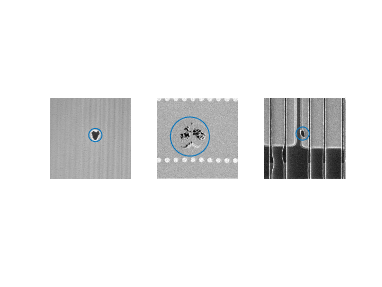

centroids_img1 = regionprops(img1bw_rev, 'Centroid');
centroids_1 = cat(1, centroids_img1.Centroid);
centroids_img2 = regionprops(img2bw_rev, 'Centroid');
centroids_2 = cat(1, centroids_img2.Centroid);
centroids_img3 = regionprops(img3bw_final, 'Centroid');
centroids_3 = cat(1, centroids_img3.Centroid);

figure;
circle_radius = 20;

subplot(1, 3, 1); imshow(image1);
circle(centroids_1(:,1), centroids_1(:,2), circle_radius);

subplot(1, 3, 2); imshow(image2);
% Image 2 has multiple centroids (detached shapes)
x_avg = mean(centroids_2(:,1));
y_avg = mean(centroids_2(:,2));
circle(x_avg, y_avg, circle_radius*3);

subplot(1, 3, 3); imshow(image3);
circle(centroids_3(:,1), centroids_3(:,2), circle_radius);

function h = circle(x,y,r)
    hold on
    th = 0:pi/50:2*pi;
    xunit = r * cos(th) + x;
    yunit = r * sin(th) + y;
    h = plot(xunit, yunit);
    hold off
end